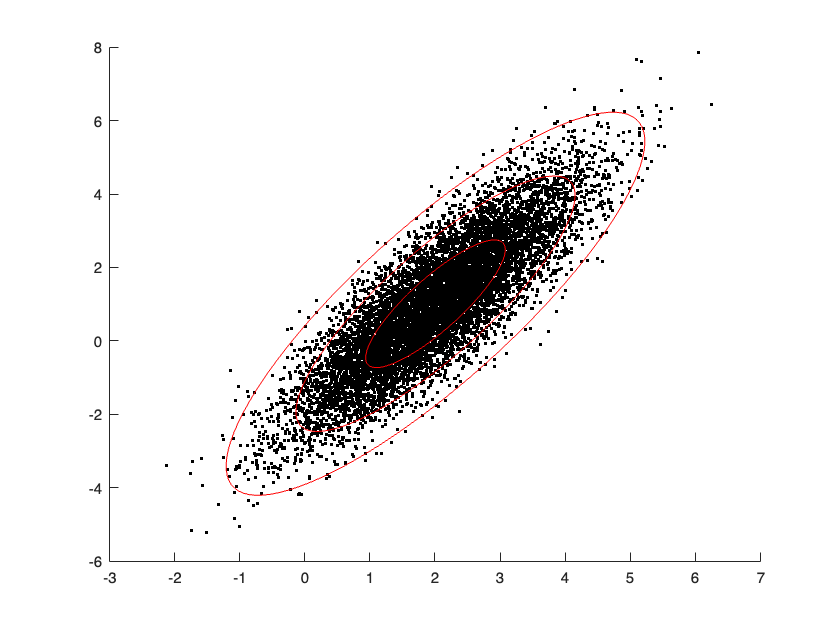

function [Xavg, V, eigenvalues] = PCA(A)

    % Center the data
    Xavg = mean(A, 1);
    B = A - ones(size(A, 1), 1) * Xavg;
    
    % Compute covariance matrix
    cov_matrix = cov(B);
    
    % Compute eigenvalues and eigenvectors
    [V, D] = eig(cov_matrix);
    
    % Sort eigenvalues and corresponding eigenvectors in descending order
    [eigenvalues, i] = sort(diag(D), 'descend');
    V = V(:, i);
    
end

xC = [2, 1];
sig = [2, .5];
theta = pi/3;
R = [cos(theta) sin(theta);

-sin(theta) cos(theta)];
nPoints = 10000;
X = randn(nPoints,2)*diag(sig)*R + ones(nPoints,2)*diag(xC); 
scatter(X(:,1),X(:,2),'k.','LineWidth',2)
hold on;

% PCA function call
[Aavg, V, eigenvalues] = PCA(X);

theta = (0:.01:1)*2*pi;
Astd = [cos(theta') sin(theta')] * sqrt(diag(eigenvalues)) * V';
plot(Aavg(1)+Astd(:,1),Aavg(2) + Astd(:,2),'r-') 
plot(Aavg(1)+2*Astd(:,1),Aavg(2) + 2*Astd(:,2),'r-') 
plot(Aavg(1)+3*Astd(:,1),Aavg(2) + 3*Astd(:,2),'r-')
hold off;

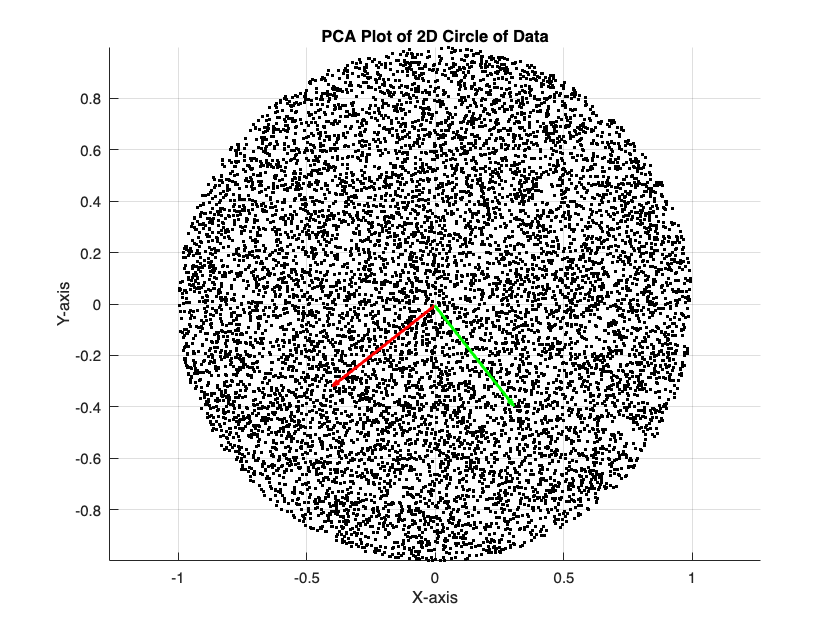


% Generate circle of data
nPoints = 10000;
r = 1;
theta = 2 * pi * rand(nPoints, 1);
radius = r * sqrt(rand(nPoints, 1));

% Convert polar coordinates to Cartesian coordinates
A = [radius .* cos(theta), radius .* sin(theta)];

% PCA function call
[Aavg, V, eigenvalues] = PCA(A);

% Plotting the 2D data
scatter(A(:,1), A(:,2), 'k.')
hold on;

% Plot the principal axes using PCA results
quiver(Aavg(1), Aavg(2), V(1,1), V(2,1), sqrt(eigenvalues(1)), 'r-', 'LineWidth', 2);
quiver(Aavg(1), Aavg(2), V(1,2), V(2,2), sqrt(eigenvalues(2)), 'g-', 'LineWidth', 2);

% Labels and view setup
xlabel('X-axis');
ylabel('Y-axis');
title('PCA Plot of 2D Circle of Data');
axis equal;
grid on;
hold off;

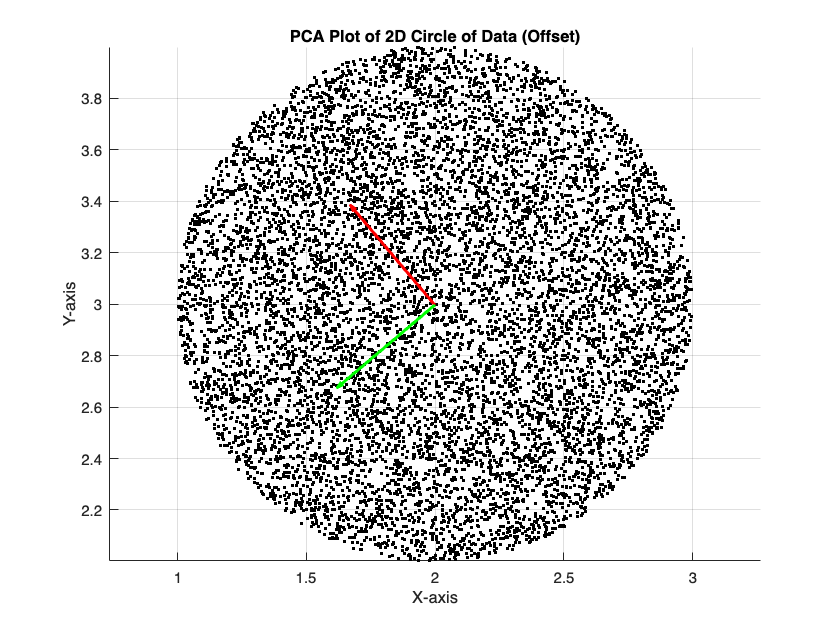


% Generate circle of data
nPoints = 10000;
r = 1;
theta = 2 * pi * rand(nPoints, 1);
radius = r * sqrt(rand(nPoints, 1));
center = [2, 3];

% Convert polar coordinates to Cartesian coordinates
X = center(1) + radius .* cos(theta);
Y = center(2) + radius .* sin(theta);
A = [X,Y];

% PCA function call
[Aavg, V, eigenvalues] = PCA(A);

% Plotting the 2D data
scatter(A(:,1), A(:,2), 'k.')
hold on;

% Plot the principal axes using PCA results
quiver(Aavg(1), Aavg(2), V(1,1), V(2,1), sqrt(eigenvalues(1)), 'r-', 'LineWidth', 2);
quiver(Aavg(1), Aavg(2), V(1,2), V(2,2), sqrt(eigenvalues(2)), 'g-', 'LineWidth', 2);

% Labels and view setup
xlabel('X-axis');
ylabel('Y-axis');
title('PCA Plot of 2D Circle of Data (Offset)');
axis equal;
grid on;
hold off;

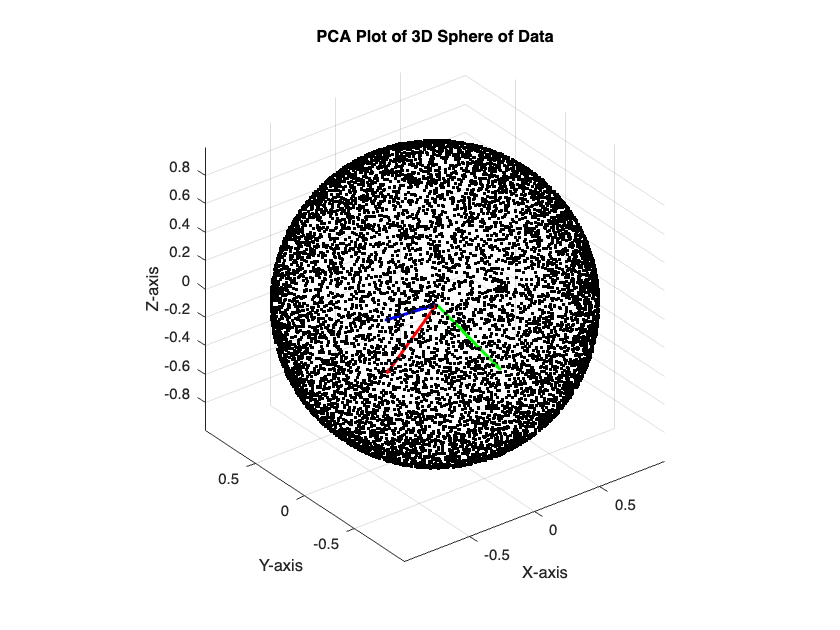


% Generate sphere of data
nPoints = 10000;
r = 1;
theta = 2 * pi * rand(nPoints, 1);
phi = acos(2 * rand(nPoints, 1) - 1);

% Convert spherical coordinates to Cartesian coordinates
A = [r * sin(phi) .* cos(theta), r * sin(phi) .* sin(theta), r * cos(phi)];

% PCA function call
[Aavg, V, eigenvalues] = PCA(A);

% Plotting the 3D data
scatter3(A(:,1), A(:,2), A(:,3), 'k.')
hold on;

% Plot the principal axes using PCA results
quiver3(Aavg(1), Aavg(2), Aavg(3), V(1,1), V(2,1), V(3,1), sqrt(eigenvalues(1)), 'r-', 'LineWidth', 2);
quiver3(Aavg(1), Aavg(2), Aavg(3), V(1,2), V(2,2), V(3,2), sqrt(eigenvalues(2)), 'g-', 'LineWidth', 2);
quiver3(Aavg(1), Aavg(2), Aavg(3), V(1,3), V(2,3), V(3,3), sqrt(eigenvalues(3)), 'b-', 'LineWidth', 2);

% Labels and view setup
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('PCA Plot of 3D Sphere of Data');
axis equal;
grid on;
hold off;